# Mohammadreza Arani

## Convex Optimization

## 810100511

## Hw8 - Q7:

clear; 
clc;
close all;
% Load Data:
run('proc_speed_data.m');

cvx_quiet(true);
% Optimal power-time tradeoff curve
Eopt = []; Topt = [];
fprintf(1,'Optimal tradeoff curve\n')

Optimal tradeoff curve


for lambda = logspace(0,-3,30)
    fprintf(1,'Solving for lambda = %1.3f\n',lambda);
    cvx_begin
        variables t(n) tau(n)
            E = sum(tau+alpha+alpha.^2.*inv_pos(tau)+...
            alpha.^3.*square_pos(inv_pos(tau)));
            minimize(lambda*E+max(t))
            subject to
            t(prec(:,2)) >= t(prec(:,1))+tau(prec(:,2))
            t >= tau
            tau >= alpha/s_max
            tau <= alpha/s_min
    cvx_end
    E = sum(tau+alpha+alpha.^2./tau+alpha.^3./(tau.^2));
    T = max(t);
    Eopt = [Eopt E];
    Topt = [Topt T];
end

Solving for lambda = 1.000
Solving for lambda = 0.788
Solving for lambda = 0.621
Solving for lambda = 0.489
Solving for lambda = 0.386
Solving for lambda = 0.304
Solving for lambda = 0.240
Solving for lambda = 0.189
Solving for lambda = 0.149
Solving for lambda = 0.117
Solving for lambda = 0.092
Solving for lambda = 0.073
Solving for lambda = 0.057
Solving for lambda = 0.045
Solving for lambda = 0.036
Solving for lambda = 0.028
Solving for lambda = 0.022
Solving for lambda = 0.017
Solving for lambda = 0.014
Solving for lambda = 0.011
Solving for lambda = 0.009
Solving for lambda = 0.007
Solving for lambda = 0.005
Solving for lambda = 0.004
Solving for lambda = 0.003
Solving for lambda = 0.003
Solving for lambda = 0.002
Solving for lambda = 0.002
Solving for lambda = 0.001
Solving for lambda = 0.001


## Tradeoff-curve for constant speed:

Econst = []; Tconst = [];
for s_const = linspace(s_min,s_max,30)
        fprintf(1,'Solving for s = %1.3f\n',s_const);
        cvx_begin
        variables t(n)
        minimize(max(t))
        subject to
        t(prec(:,2)) >= t(prec(:,1))+alpha(prec(:,2))/s_const
        t >= alpha/s_const
        cvx_end
        E = sum(alpha*(1/s_const+1+s_const+s_const^2));
        T = max(t);
        Econst = [Econst E];
        Tconst = [Tconst T];
end

Solving for s = 1.000
Solving for s = 1.138
Solving for s = 1.276
Solving for s = 1.414
Solving for s = 1.552
Solving for s = 1.690
Solving for s = 1.828
Solving for s = 1.966
Solving for s = 2.103
Solving for s = 2.241
Solving for s = 2.379
Solving for s = 2.517
Solving for s = 2.655
Solving for s = 2.793
Solving for s = 2.931
Solving for s = 3.069
Solving for s = 3.207
Solving for s = 3.345
Solving for s = 3.483
Solving for s = 3.621
Solving for s = 3.759
Solving for s = 3.897
Solving for s = 4.034
Solving for s = 4.172
Solving for s = 4.310
Solving for s = 4.448
Solving for s = 4.586
Solving for s = 4.724
Solving for s = 4.862
Solving for s = 5.000


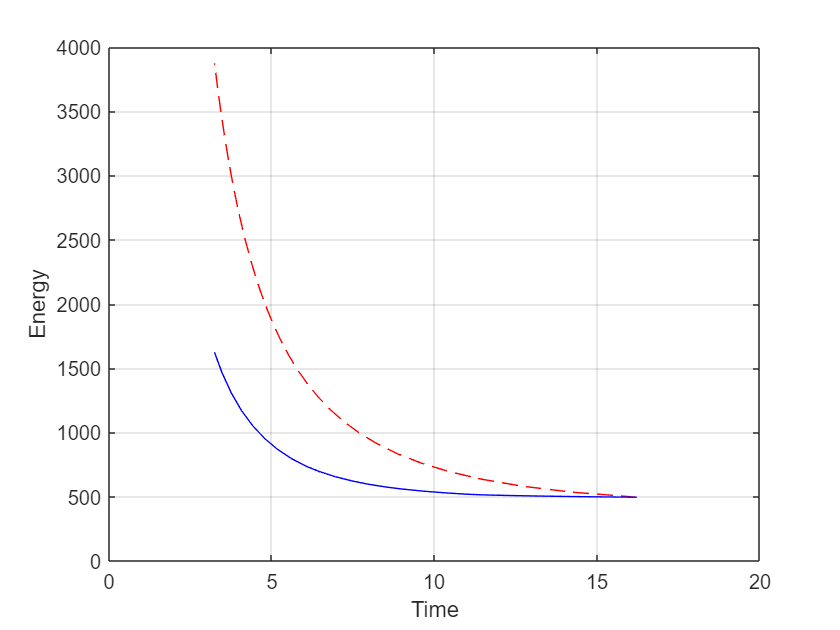

Fig1 = figure();
plot(Tconst,Econst,'r--')
hold on
plot(Topt,Eopt,'b-')
xlabel('Time')
ylabel('Energy')
grid on
axis([0 20 0 4000])